**1. a) Visualize continuous period signal x(t) = 2 + 3*cos(500*pi*t) + 2*cos(1000*pi*t) + 3*sin(2000*pi*t) in time-domain (axis: Amplitude and t) (5 points)**

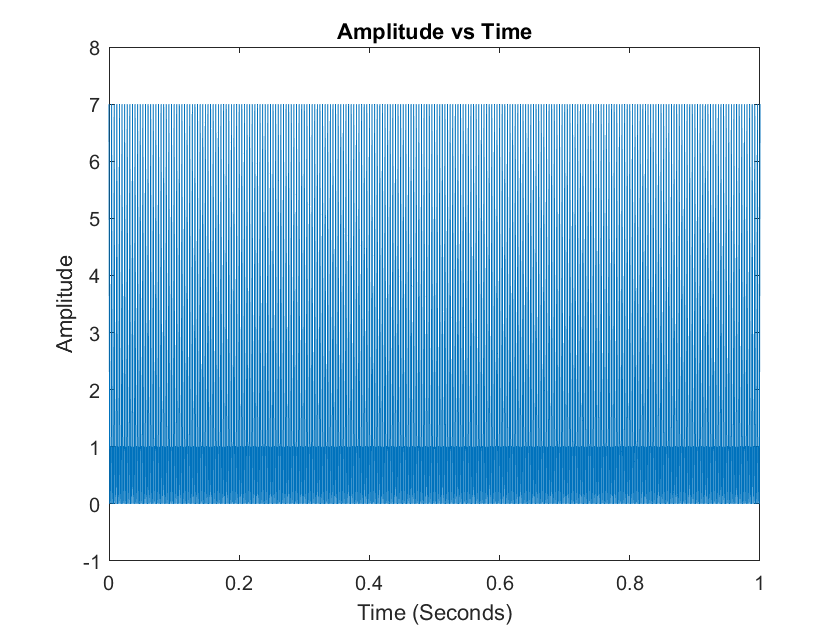

fs = 1000;
t = 0:1/fs:1;
x = 2 + 3*cos(500*pi*t) + 2*cos(1000*pi*t) + 3*sin(2000*pi*t);
plot(t,x)
xlabel('Time (Seconds)')
ylabel('Amplitude')
title('Amplitude vs Time')

**b) visualize its digital Fast Fourier transform (axis: Amplitude and f). Given Sampling frequency as 1K HZ. (5 points)**

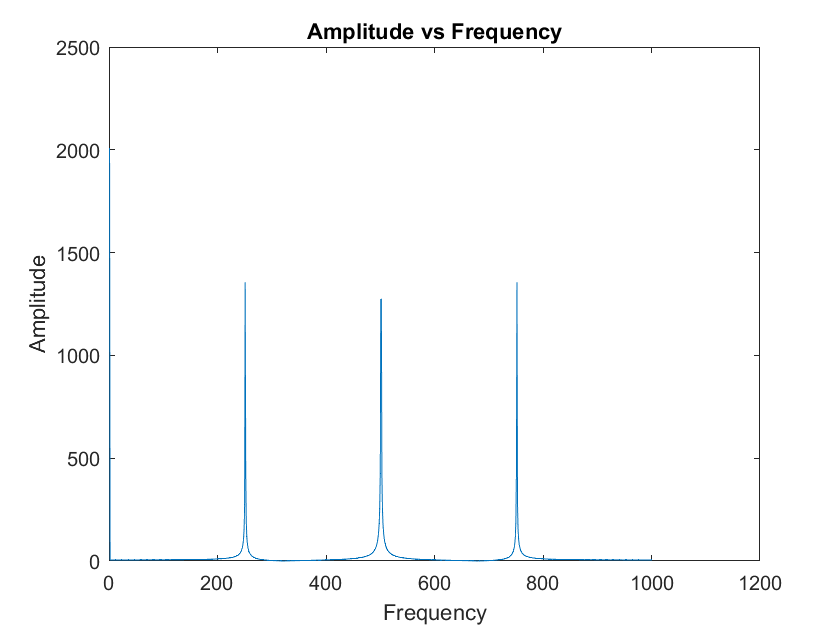

X = fft(x);                                                     
X_mag = abs(X);        
plot(X_mag) 
xlabel('Frequency')
ylabel('Amplitude')
title('Amplitude vs Frequency')

**2. a) Visualize the discrete signal x(k) = 0 for k **$\in$ **[0 499] & x(k) = 1 for k **$\in$** [500 1000)**$\mu$**s (sampling frequency as 1M HZ) in time-domain (Amplitude and t) (5 points);**

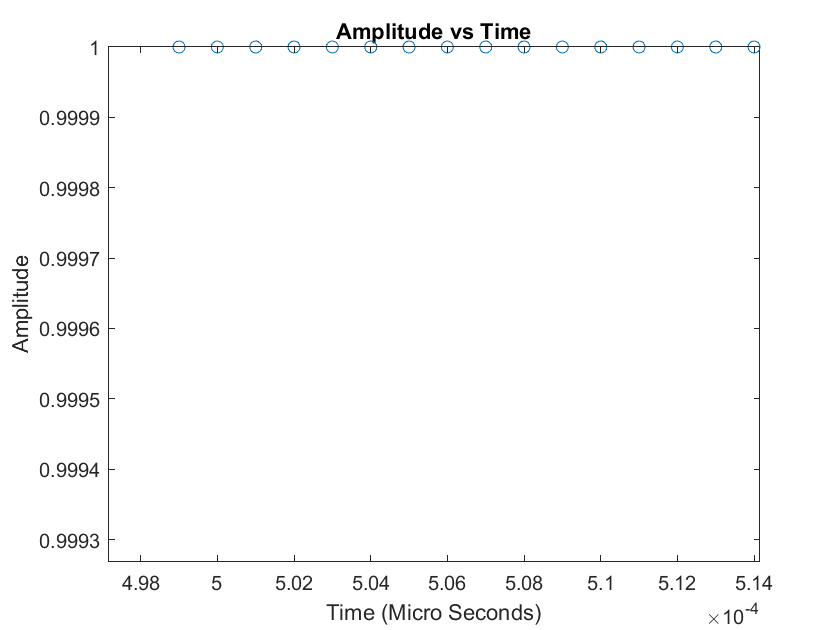

fs = 1000000;

for t = [0:499]
    x = zeros(1,499);
end
for t = [500:999]
    x(end+1) = ones(1,1);
end

L = length(x);
T = (0:L-1)*1/fs;

figure
stem (T,x, "LineStyle","none");
xlabel('Time (Micro Seconds)')
ylabel('Amplitude')
title('Amplitude vs Time')
ylabel('Amplitude')
title('Amplitude vs Time')

**b) Visualize its digital Fast Fourier transform (Amplitude and f), find its -3dB (called half-power) bandwidth frequencies (f_low, f_high) in frequency spectrum. (15 points)**

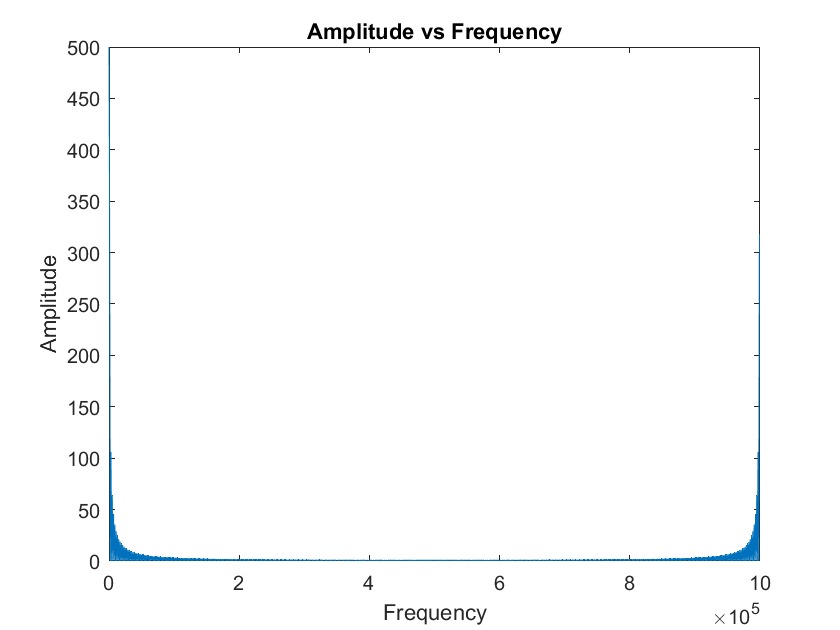

fs = 1000000;

for t = [0:499]
    x = zeros(1,499);
end
for t = [500:999]
    x(end+1) = ones(1,1);
end

y = abs(fft(x));
F = fs*(0:(L-1))/L;

figure
plot(F, y);
xlabel('Frequency')
ylabel('Amplitude')
title('Amplitude vs Frequency')

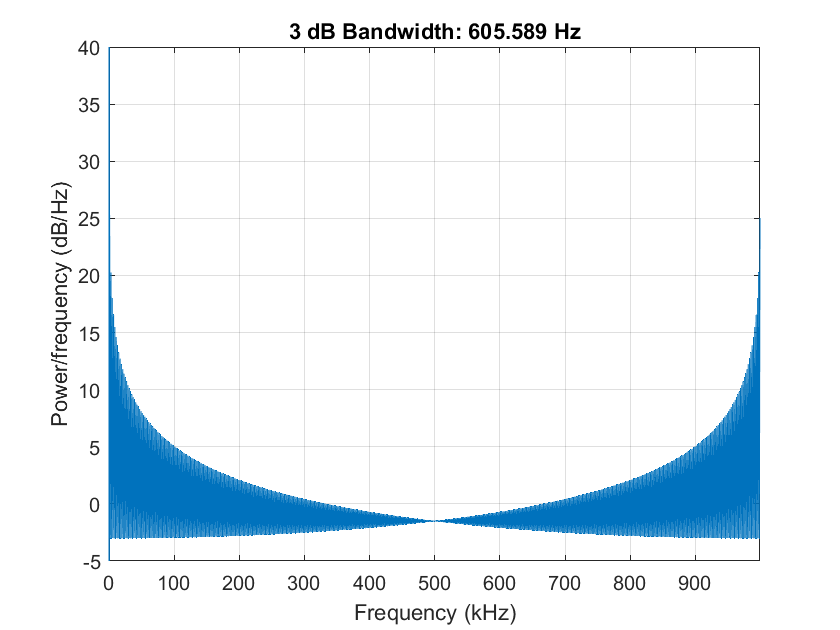


figure
powerbw(y, F);

[bw,f_low,f_high,poweAr] = powerbw(y, F)

bw = 605.5886

f_low = 0

f_high = 605.5886

poweAr = 5.3392e+05

**3. For discrete signal x(k) = 20 for k **$\in$**[0 499], add a normally distributed random noise n(k) (mean 0, variance 1) to the signal, and get x*****'*****(k) = x(k) + n(k). ****Then, apply a normalized (mean 0, standard deviation 1) Gaussian kernel (windows size 3 and 11 respectively as a low pass filter, then rescale all elements to make sure the sum is 1) to perform convolution y(k) = x*****'*****(k) * h(k) (h presents the impulse response, and in this case it’s the filter) by using basic arithmetic operations only. (Implement the convolution without using library API)**

**a) Visualize both x(k) and x*****'*****(k) in one figure (10 points)**

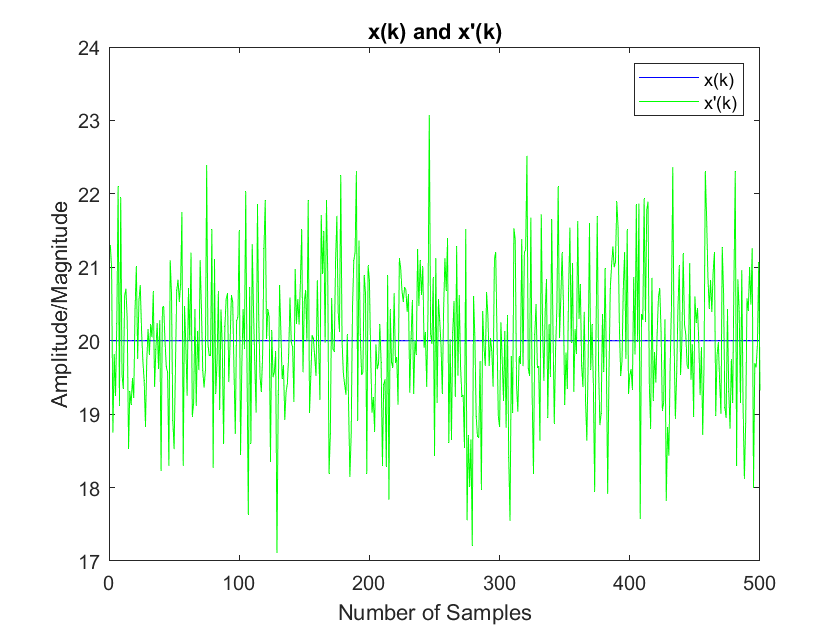

x_k = [];

for t = [0:499]
    x_k(end+1) = 20;
end

noise = normrnd(0, 1, 1, 500);
noisy_x = x_k + noise;

plot(x_k, "Color", "blue")
hold on
plot(noisy_x, "Color", "Green")
legend("x(k)", "x'(k)")
title("x(k) and x'(k)")
xlabel("Number of Samples")
ylabel("Amplitude/Magnitude")
hold off

**b) Visualize both x(k), and y(k) based on kernel window size 3 in one figure (15 points)**

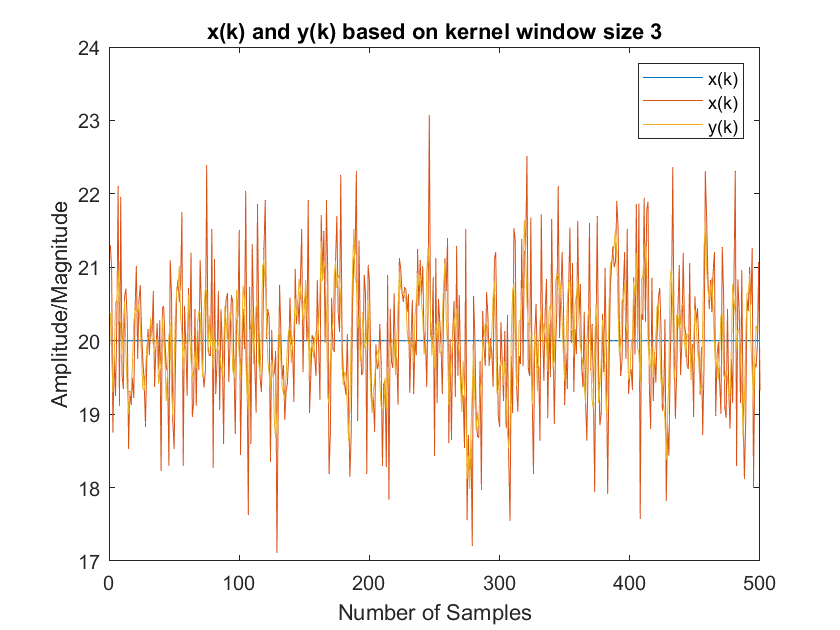

h_k = [0.31946576033846985, 0.3610684793230603, 0.31946576033846985];

i = 0;
n = 1;
new_array= [0];
y_k = [0];

for i = [0:1:497]
    P = noisy_x(1+i:3+i).*h_k;
    Q(1+i:3+i) = P;
    y_k(n) = sum(Q(1, 1+i:3+i));
    n = n+1;
end

figure
plot(x_k)
hold on
plot(noisy_x)
hold on
plot(y_k)


title("x(k) and y(k) based on kernel window size 3")
legend("x(k)", "x(k)", "y(k)");
xlabel("Number of Samples")
ylabel("Amplitude/Magnitude")

**c) Visualize both x(k), and y(k) based on kernel window size 11 in one figure (5 points)**

**Tip: You may consider using zero-padded for edges during convolution operation**

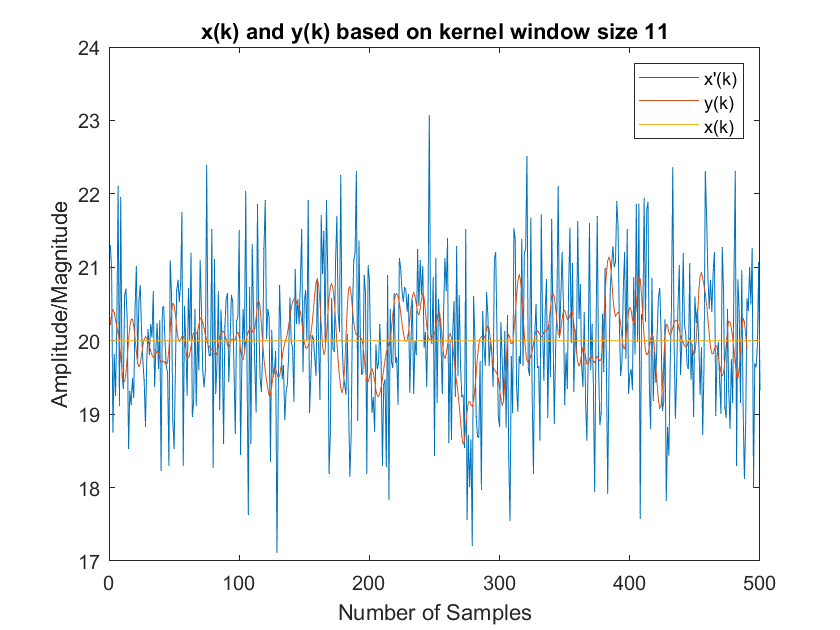

h_k = [0.009300040045324049, 0.028001560233780885, 0.06598396774984912,0.12170274650962626, 0.17571363439579307, 0.19859610213125314, 0.17571363439579307, 0.12170274650962626, 0.06598396774984912, 0.028001560233780885, 0.009300040045324049];

i = 0;
n = 1;
new_array= [0];
y_k = [0];

for i = [0:1:489]
    P = noisy_x(1+i:11+i).*h_k;
    Q(1+i:11+i) = P;
    y_k(n) = sum(Q(1, 1+i:11+i));
    n = n+1;
end

figure
plot(noisy_x)
hold on
plot(y_k)
plot(x_k)
title("x(k) and y(k) based on kernel window size 11")
legend("x'(k)", "y(k)", "x(k)");
xlabel("Number of Samples")
ylabel("Amplitude/Magnitude")